# ADRC Toolbox tutorial

## First example

This example will concern the simple object described with 4th order transfer function

 
$$G(s) = \frac{1}{s^4 + 4s^3 + 6s^2 + 4s + 1}$$
   

First load the system 

load_system('simple_example');

Make simulation

results = sim('simple_example.slx');

Plot results

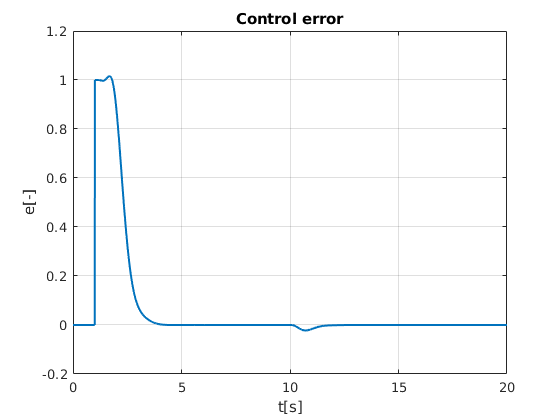

controlError = get(results.logsout,'controlError');
plot(controlError.Values.Time, ...
    controlError.Values.Data, ...
    'LineWidth', 1.5);
grid on;
xlabel('t[s]'), ...
ylabel('e[-]'), ...
title('Control error')

And close the system

close_system('simple_example', 0);